# crossthreshold_demo.mlx

see also

`crossthreshold`

x = linspace(0,1,1000);

Pos = [1 2 3 5 7 8]/10;
Hgt = [4 4 4 2 2 3];
Wdt = [2 6 3 3 4 6]/100;

for n = 1:length(Pos)
    Gauss(n,:) =  Hgt(n)*exp(-((x - Pos(n))/Wdt(n)).^2);
end

PeakSig = sum(Gauss);


## Rising

figure
plot(x,PeakSig) % see also doc findpeaks

out = crossthreshold('rising',PeakSig',2)

out =     84
   151
   691
   755


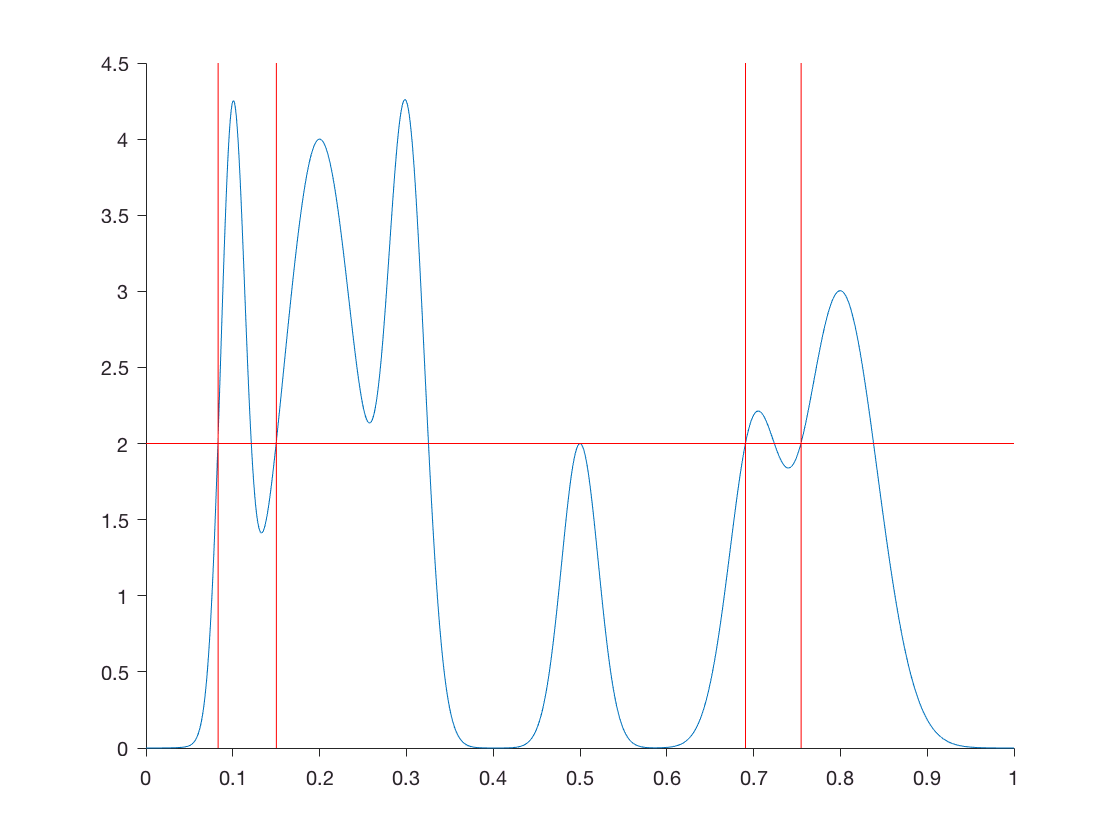


hold on
plot(repmat(x(out),2,1),repmat(ylim',1,length(out)),'r')

plot(xlim,[2 2],'r')

set(gca,'TickDir','out','box','off')

## Falling

figure
plot(x,PeakSig) % see also doc findpeaks

out = crossthreshold('falling',PeakSig',3)

out =    115
   234
   318
   803


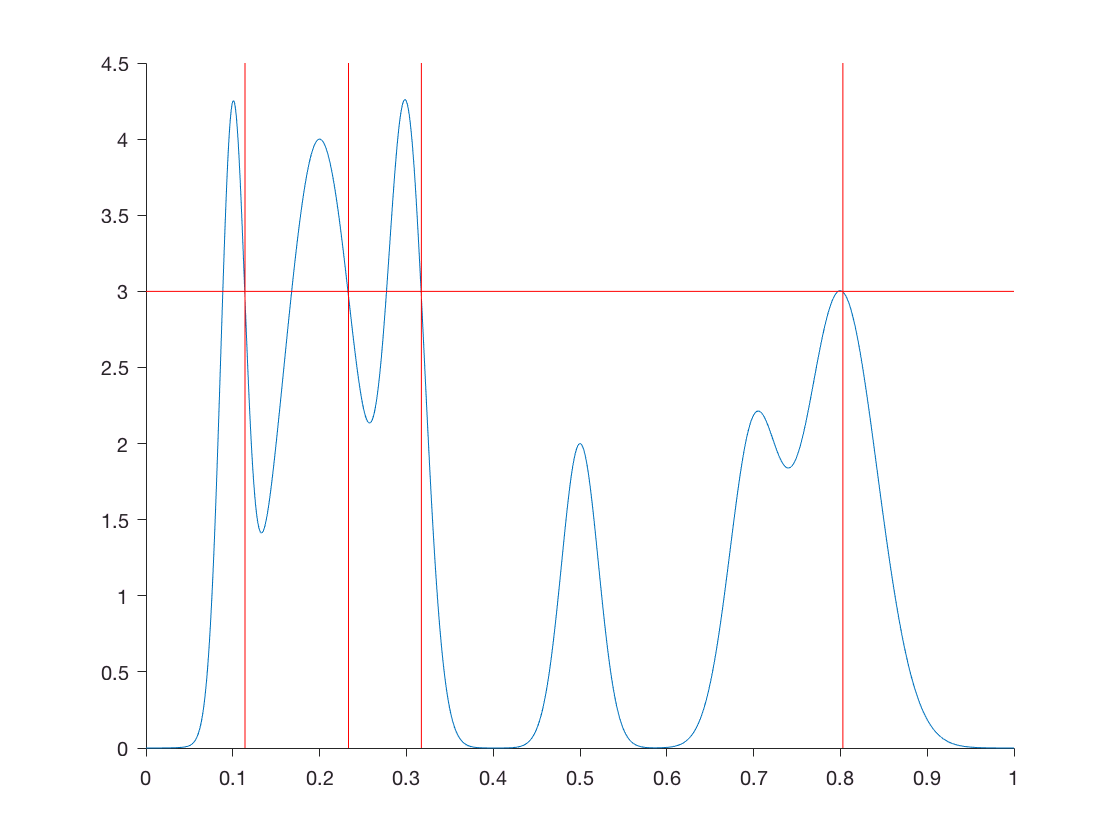


hold on
plot(repmat(x(out),2,1),repmat(ylim',1,length(out)),'r')

plot(xlim,[3 3],'r')

set(gca,'TickDir','out','box','off')

## Rising + mincross

figure
plot(x,PeakSig) % see also doc findpeaks

out = crossthreshold('rising',PeakSig',2,'mincross',1.5)

out =     84
   151


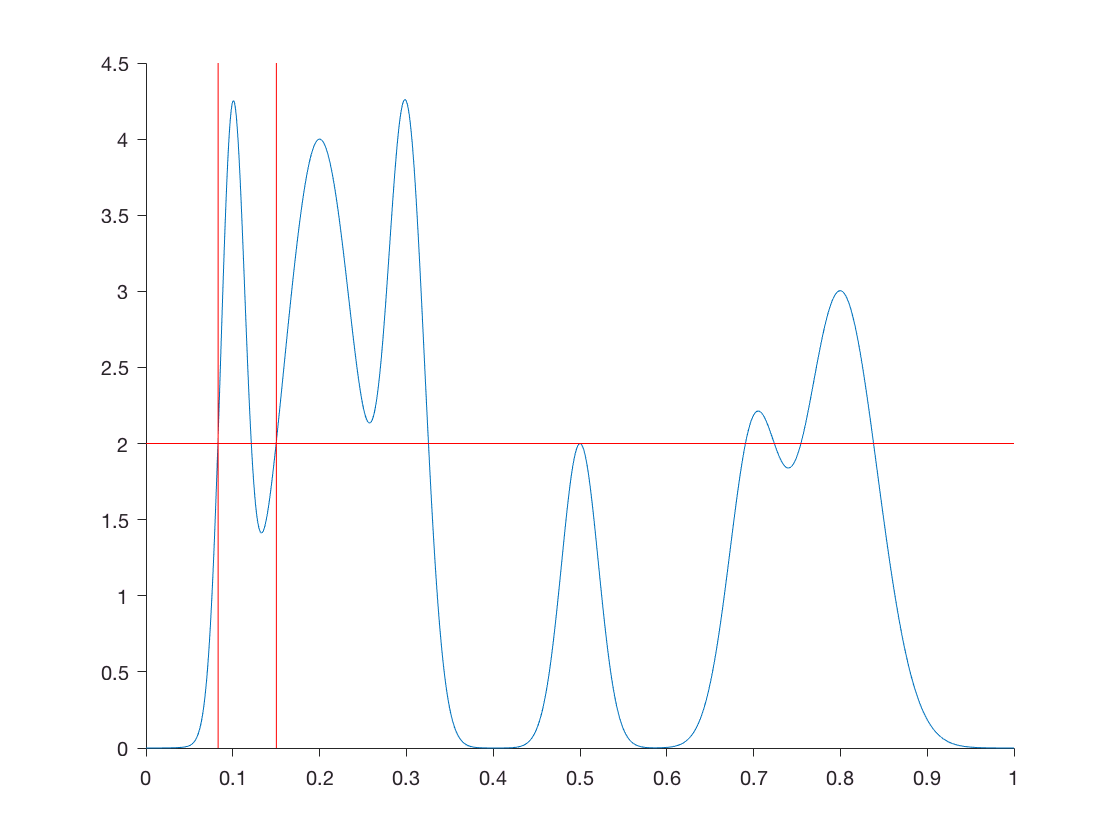


hold on
plot(repmat(x(out),2,1),repmat(ylim',1,length(out)),'r')

plot(xlim,[2 2],'r')

set(gca,'TickDir','out','box','off')

## Falling + mincross

figure
plot(x,PeakSig) % see also doc findpeaks

out = crossthreshold('falling',PeakSig',3,'mincross',1)

out =    115
   318
   803


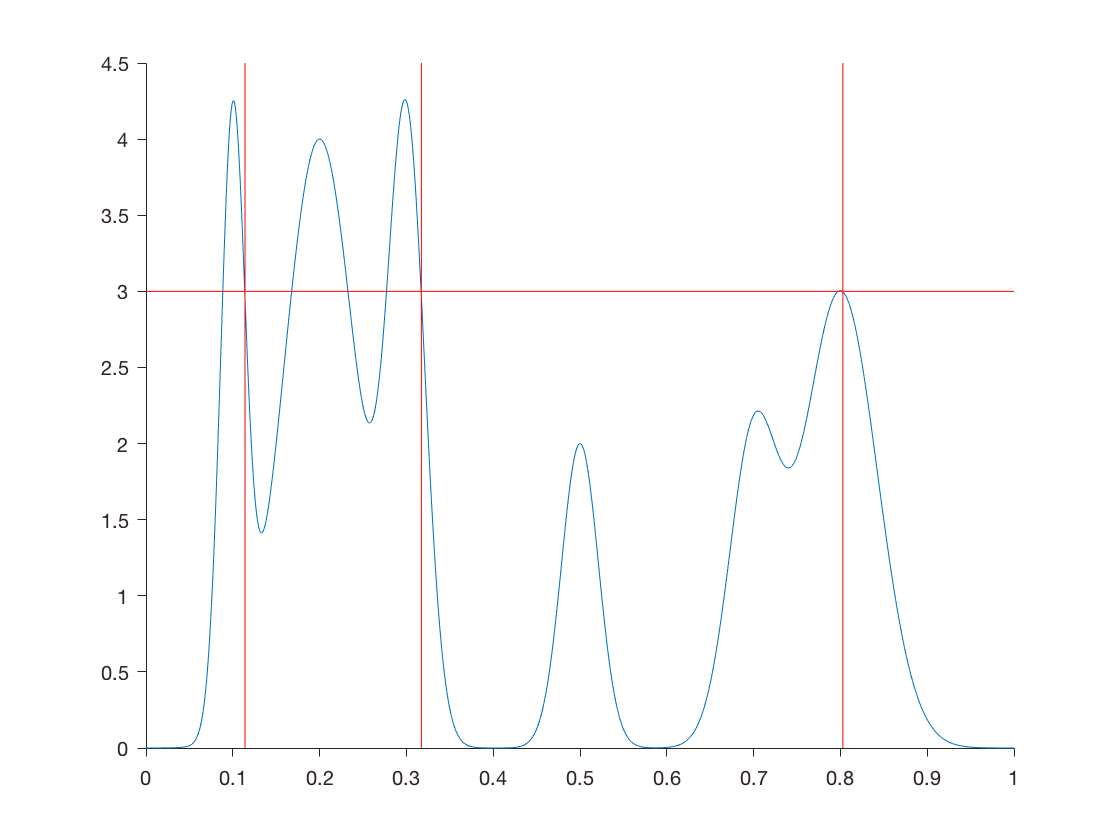


hold on
plot(repmat(x(out),2,1),repmat(ylim',1,length(out)),'r')

plot(xlim,[3 3],'r')

set(gca,'TickDir','out','box','off')

## Rising + mindelay

figure
plot(x,PeakSig) % see also doc findpeaks

out0 = crossthreshold('rising',PeakSig',2,'Fs',1/(x(2)-x(1)))

out0 =     84
   151
   691
   755



out1 = crossthreshold('rising',PeakSig',2,'mindelay',0.1,'Fs',1/(x(2)-x(1)))

out1 = 151

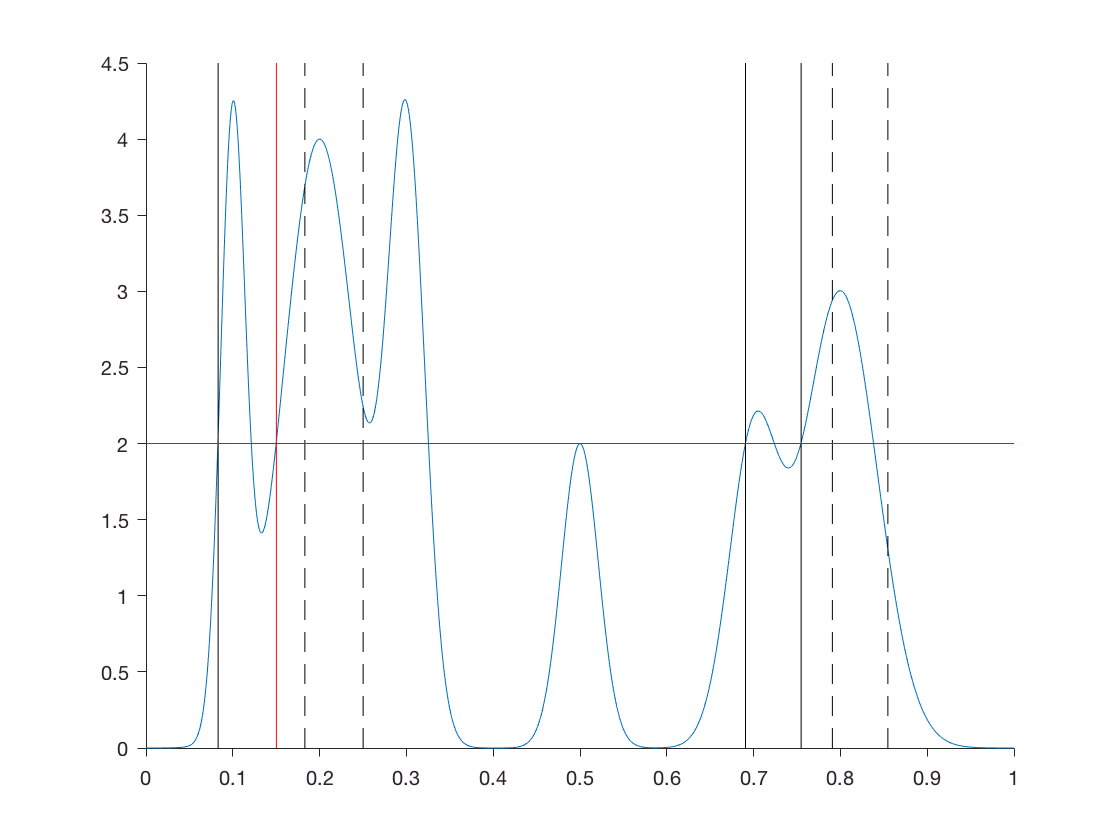


hold on
plot(repmat(x(out0),2,1),repmat(ylim',1,length(out0)),'k')
plot(repmat(x(out0),2,1) + 0.1,repmat(ylim',1,length(out0)),'k--')

plot(repmat(x(out1),2,1),repmat(ylim',1,length(out1)),'r')

plot(xlim,[2 2],'r')

set(gca,'TickDir','out','box','off')

## Rising + mindelay 2

figure
plot(x,PeakSig) % see also doc findpeaks

out0 = crossthreshold('rising',PeakSig',2,'Fs',1/(x(2)-x(1)))

out0 =     84
   151
   691
   755



out1 = crossthreshold('rising',PeakSig',2,'mindelay',0.05,'Fs',1/(x(2)-x(1)))

out1 =    151
   755


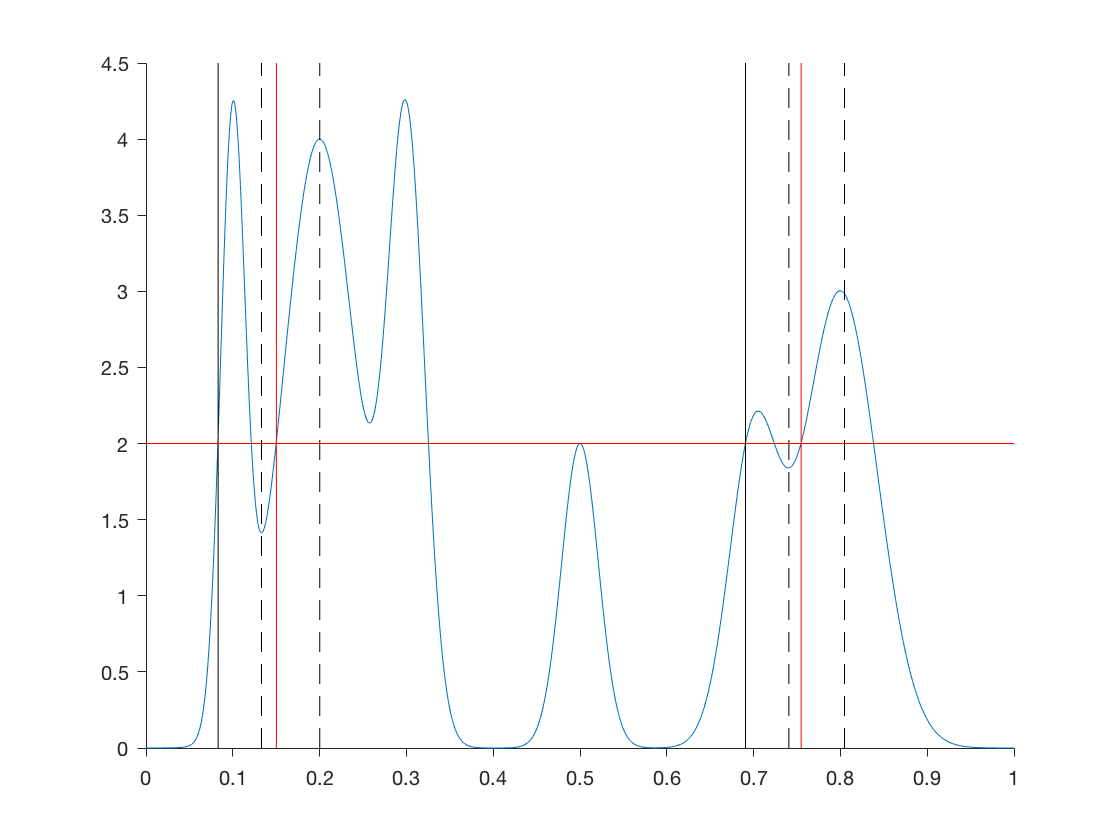


hold on
plot(repmat(x(out0),2,1),repmat(ylim',1,length(out0)),'k')
plot(repmat(x(out0),2,1) + 0.05,repmat(ylim',1,length(out0)),'k--')

plot(repmat(x(out1),2,1),repmat(ylim',1,length(out1)),'r')

plot(xlim,[2 2],'r')

set(gca,'TickDir','out','box','off')